**This discuss how this problem can be appoched as a multi class problem**

**Note:**

**    - The KDD Cup 1999 dataset contains 23 specific attack types. **

**Data Loading and Preprocessing for training the model**

clear all;
close all;

% Load the processed data from the previous step
fprintf('Loading processed data from "../Data/data_for_preprocessing.mat"...\n');

Loading processed data from "../Data/data_for_preprocessing.mat"...


load('../Data/data_for_preprocessing.mat', 'newp');
fprintf('Processed data loaded successfully.\n');

Processed data loaded successfully.


disp(head(newp, 10));  % Display the first 10 rows; you can adjust the number as needed

   1.0e+03 *

         0    0.0020    0.0230    0.0100    0.1810    5.4500         0         0         0         0         0    0.0010         0         0         0         0         0         0         0         0         0         0    0.0080    0.0080         0         0         0         0    0.0010         0         0    0.0090    0.0090    0.0010         0    0.0001         0         0         0         0         0    0.0120
         0    0.0020    0.0230    0.0100    0.2390    0.4860         0         0         0         0         0    0.0010         0         0         0         0         0         0         0         0         0         0    0.0080    0.0080         0         0         0         0    0.0010         0         0    0.0190    0.0190    0.0010         0    0.0001         0         0         0         0         0    0.0120
         0    0.0020    0.0230    0.0100    0.2350    1.3370         0         0         0         0         0    0.0010         0         0    


% Separate input features and target labels
dataInputs = newp(:, 1:41)';  % Transpose for easier handling (each column is a sample)
dataTargets = newp(:, 42)';   % Target labels



fprintf('Shuffling data...\n');

Shuffling data...



% Determine the total number of samples in the dataset
numTotalSamples = size(dataInputs, 2);  % Each of 2nd dimention of the matrix dataInputs (here it is 42)

randIndices = randperm(numTotalSamples);  % Generate a random permutation of indices
dataInputs = dataInputs(:, randIndices);  % Shuffle the input data columns
dataTargets = dataTargets(randIndices);   % Shuffle the target labels accordingly
fprintf("Data has been shuffled successfully")

Data has been shuffled successfully

fprintf('Handling missing values in the input data...\n');

Handling missing values in the input data...


colMeans = mean(dataInputs, 2, 'omitnan');  % Calculate mean for each feature, ignoring NaNs
% here, 2 denoted the column, second dimension.

for j = 1:size(dataInputs, 1)
    nanIdx = isnan(dataInputs(j, :));         % Find indices with NaN values
    if any(nanIdx)
        dataInputs(j, nanIdx) = colMeans(j);  % Replace NaN values with the column mean
        fprintf('Replaced NaN values in feature %d with column mean.\n', j);
    end
end

% Replace NaNs in dataTargets with the mode (most frequent value)
if any(isnan(dataTargets))
    dataTargets(isnan(dataTargets)) = mode(dataTargets);
    fprintf('Replaced NaN values in target labels with mode value.\n');
end
fprintf("Missing values has been handled...")

Missing values has been handled...

fprintf('Normalizing input data...\n');

Normalizing input data...



% Normalize each feature to range [0, 1]
dataInputs = (dataInputs - min(dataInputs, [], 2)) ./ (max(dataInputs, [], 2) - min(dataInputs, [], 2) + eps); 

fprintf('Data normalization completed\n');

Data normalization completed


## Step 4 from the previous code has been skipped since it is a multiclass problem

## Data Splitting 

    80% for Training

    20% for Testing

numTotalSamples = size(dataInputs, 2);  % Each column is a sample
testSampleCount = round(0.2 * numTotalSamples);  % Calculate 20% of total samples

% Shuffle data
randIndices = randperm(numTotalSamples);  % Generate random permutation of indices

% Select 20% of the data for the test set
testIndices = randIndices(1:testSampleCount);               % First 20% as test set indices
trainIndices = randIndices(testSampleCount+1:end);          % Remaining 80% as training set indices

% Split data based on the selected indices
trainingInputs = dataInputs(:, trainIndices);               % 80% as training inputs
trainingTargets = dataTargets(trainIndices);                % 80% as training targets
testInputs = dataInputs(:, testIndices);                    % 20% as test inputs
testTargets = dataTargets(testIndices);                     % 20% as test targets

% Verify split
fprintf('Training set size: %d samples\n', size(trainingInputs, 2));

Training set size: 395217 samples


fprintf('Test set size: %d samples\n', size(testInputs, 2));

Test set size: 98804 samples



% Save the trained network, training record, test inputs, and test targets
fprintf('Saving Train Inputs, Train Targets, Test inputs, and test targets to "outputs/"...\n');

Saving Train Inputs, Train Targets, Test inputs, and test targets to "outputs/"...


save('../Data/multiclass_preprocessed_data.mat', 'trainingInputs', 'trainingTargets', 'testInputs', 'testTargets');
fprintf('Train Inputs, Train Targets, Test inputs, and test targets saved successfully.\n');

Train Inputs, Train Targets, Test inputs, and test targets saved successfully.


**Model Training**

% Configure the network with the best estimated feasible hyperparameters
fprintf('Configuring neural network with estimated best hyperparameters...\n');

Configuring neural network with estimated best hyperparameters...



% Define hidden layer size with 1 layer and 29 neurons
bestHiddenLayerSize = repmat(29, 1, 1);

% Initialize network with specified hidden layers
net = feedforwardnet(bestHiddenLayerSize);

% Set training parameters
net.trainFcn = 'traincgp';         % Conjugate Gradient with Powell/Beale Restarts
net.performFcn = 'mse';            % Mean Squared Error
net.trainParam.lr = 0.051679;      % Learning rate
net.trainParam.mc = 0.68386;       % Momentum
net.trainParam.epochs = 25;        % Number of training epochs
net.divideFcn = 'dividetrain';     % Use all data without further internal split


% Set activation function for the hidden layer
net_best.layers{1}.transferFcn = 'purelin';  % Pure linear function for hidden layer


tic
% Train the network on the entire training dataset
fprintf('Training the neural network with estimated best hyperparameters...\n');

Training the neural network with estimated best hyperparameters...


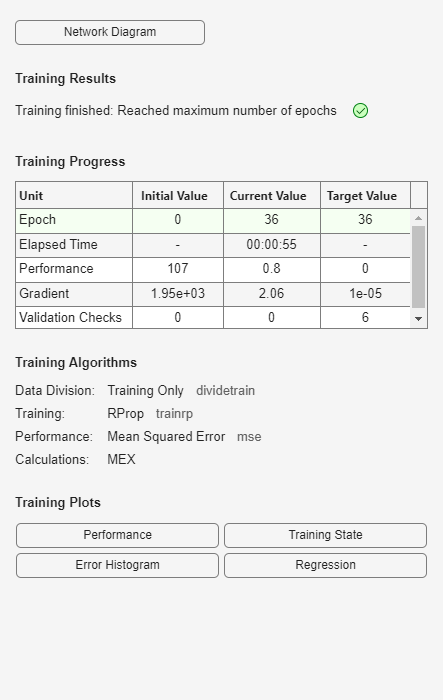

[net, tr] = train(net, trainingInputs, trainingTargets);

toc

Elapsed time is 31.557436 seconds.


**Saving the Plots**


% save the 4 plots which comes in the UI after training
% Save generated plots after training
fprintf('Saving generated plots...\n');

Saving generated plots...


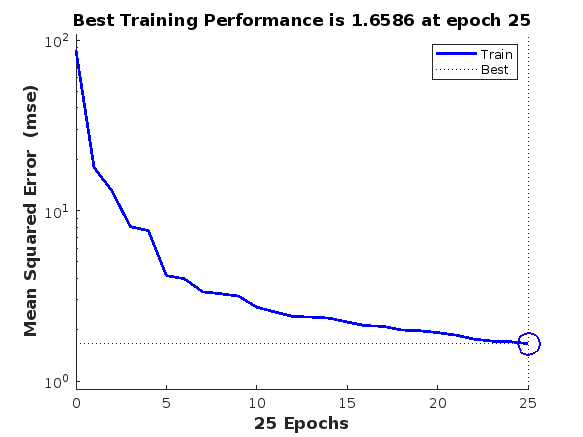


% Performance Plot
if isfield(tr, 'perf')
    figure, plotperform(tr);  % Generate the performance plot
    exportgraphics(gcf, '../outputs/multiclass_performance_plot_best_feasible.png', 'Resolution', 300);  % Save performance plot with high resolution
    %close(gcf);  % Close the figure after saving
end

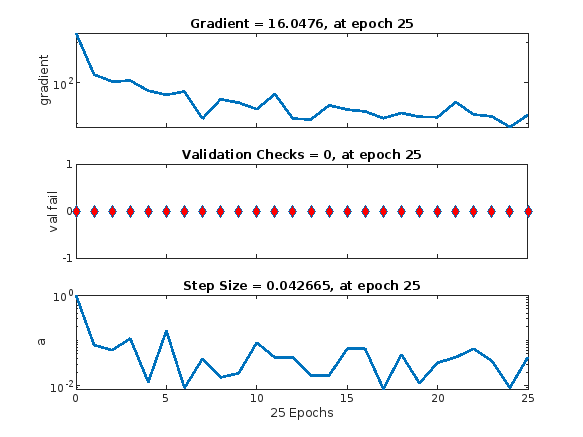


% Training State Plot
if isfield(tr, 'states')
    figure, plottrainstate(tr);  % Generate the training state plot
    exportgraphics(gcf, '../outputs/multiclass_training_state_plot_best_feasible.png', 'Resolution', 300);  % Save training state plot with high resolution
    %close(gcf);
end


fprintf('All plots saved successfully.\n');

All plots saved successfully.


**Performance Matrices**

% Plot Training Progress for Training and Validation Loss and save
fprintf('Saving training progress plot to "../outputs/multiclass_training_progress_best_feasible.png"...\n');

Saving training progress plot to "../outputs/multiclass_training_progress_best_feasible.png"...


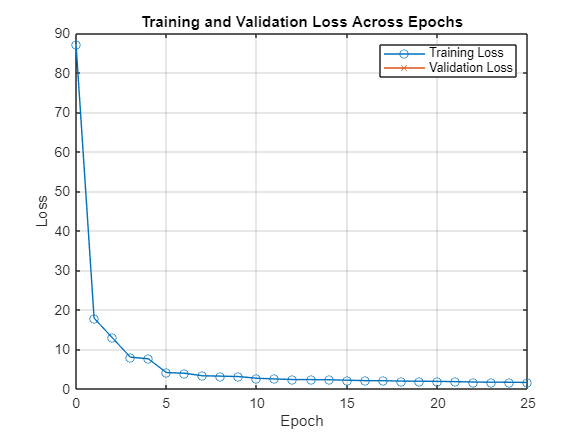

figure;
plot(tr.epoch, tr.perf, '-o', 'DisplayName', 'Training Loss');  % Plot training loss
hold on;
plot(tr.epoch, tr.vperf, '-x', 'DisplayName', 'Validation Loss');  % Plot validation loss

% Labels and styling
xlabel('Epoch');
ylabel('Loss');
title('Training and Validation Loss Across Epochs');
legend;
grid on;

% Save the plot as high-resolution image
exportgraphics(gcf, '../outputs/multiclass_training_progress_best_feasible.png', 'Resolution', 300);

%%close(gcf);  % Close the figure after saving
fprintf('Training progress plot saved successfully.\n');

Training progress plot saved successfully.




% Save the trained network and training record with custom names
fprintf('Saving trained model to "Data/multiclass_final_model_best_feasible.mat"...\n');

Saving trained model to "Data/multiclass_final_model_best_feasible.mat"...


save('../Data/multiclass_final_model_best_feasible.mat', 'net', 'tr');
fprintf('Trained model saved successfully.\n');

Trained model saved successfully.


## Prediction

% Load trained model and test data
fprintf('Loading trained model from "Data/multiclass_final_model_best_feasible.mat"...\n');

Loading trained model from "Data/multiclass_final_model_best_feasible.mat"...


load('../Data/multiclass_final_model_best_feasible.mat', 'net');
fprintf('Best Feasible Trained model loaded successfully.\n');

Best Feasible Trained model loaded successfully.




% Perform predictions on the test data
fprintf('Predicting on the test data...\n');

Predicting on the test data...


predictedTestOutputs = net(testInputs);  % Raw outputs from network
predictedTestLabels = round(predictedTestOutputs);  % Convert to binary labels (assuming threshold of 0.5)


disp(['Number of unique classes in predicted labels: ', num2str(numel(unique(predictedTestLabels)))]);

Number of unique classes in predicted labels: 36


disp(['Number of unique classes in True labels: ', num2str(numel(unique(testTargets)))]);

Number of unique classes in True labels: 22


% Calculate accuracy
numCorrect = sum(predictedTestLabels == testTargets);
accuracy = numCorrect / length(testTargets) * 100;
fprintf('Accuracy on Test Data: %.2f%%\n', accuracy);

Accuracy on Test Data: 75.94%



% Save accuracy in a text file
metricsFile = fopen('../outputs/multiclass_metrics_best_feasible.txt', 'w');
fprintf(metricsFile, 'Accuracy on Test Data: %.2f%%\n', accuracy);
fclose(metricsFile);


% Generate and save Confusion Matrix
fprintf('Generating confusion matrix...\n');

Generating confusion matrix...


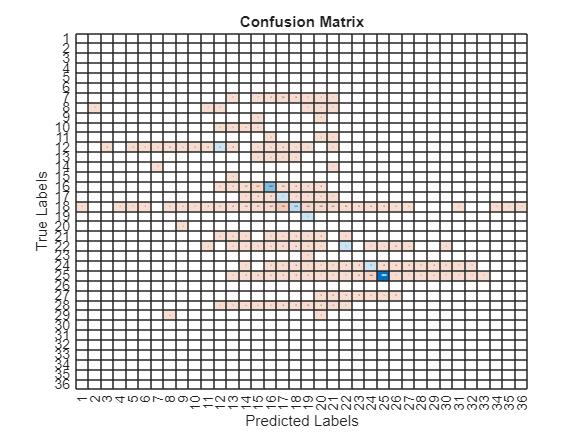

% Compute the rounded confusion matrix
confMat = round(confusionmat(testTargets, predictedTestLabels));

% Display the confusion matrix using confusionchart
figure;
cm = confusionchart(confMat);

% Set properties to show numbers without scientific notation
cm.CellLabelFormat = '%d';  % Format labels as integers

% Customize the chart title and labels as needed
cm.Title = 'Confusion Matrix';
cm.XLabel = 'Predicted Labels';
cm.YLabel = 'True Labels';

% Save the confusion matrix plot as a high-resolution PNG file
exportgraphics(gcf, '../outputs/multiclass_confusion_matrix_best_feasible.png', 'Resolution', 300);

fprintf('Confusion matrix saved as "outputs/multiclass_confusion_matrix_best_feasible.png" with high resolution.\n');

Confusion matrix saved as "outputs/multiclass_confusion_matrix_best_feasible.png" with high resolution.


**Observation**:

    From the output, it appears that:

- Number of unique classes in predicted labels: 36

- Number of unique classes in true labels: 22

- but the confusion matrix shows 36

- The reason could be that **the model failed to predict some of the classes.**

# The Reason:

#     - Small Dataset

#     - Class Imbalance

Finding Missing classes in the '`testTargets'` and '`predictedTestLabels'`

% Find classes present in true labels but not in predictions
missingInPredicted = setdiff(unique(testTargets),unique(predictedTestLabels));
disp('Classes present in True Labels but missing in Predicted Labels:');

Classes present in True Labels but missing in Predicted Labels:


disp(missingInPredicted');

% Find classes present in predictions but not in true labels (unlikely, but possible)
missingInTrue = setdiff(unique(predictedTestLabels),unique(testTargets));
disp('Classes present in Predicted Labels but missing in True Labels:');

Classes present in Predicted Labels but missing in True Labels:


disp(missingInTrue');

   -11
    -9
    -4
    -2
    -1
     0
    20
    24
    25
    26
    27
    28
    29
    31



% Count occurrences of each class in true labels
[trueCounts, edges] = histcounts(testTargets, 1:max(testTargets)+1);
trueClasses = edges(1:end-1); % Extract class labels from edges
disp('Class distribution in True Labels:');

Class distribution in True Labels:


disp(table(trueClasses', trueCounts', 'VariableNames', {'Class', 'Count'}));

    Class    Count
    _____    _____

      1        444
      2          9
      3          2
      4          9
      5          3
      6        251
      7          4
      8          2
      9          1
     10      21551
     11         50
     12      19443
     13          1
     14          1
     15         47
     16        233
     17          1
     18        314
     19      56030
     20          0
     21        207
     22        196
     23          5




% Count occurrences of each class in predicted labels
[predCounts, edges] = histcounts(predictedTestLabels, 1:max(predictedTestLabels)+1);
predClasses = edges(1:end-1); % Extract class labels from edges
disp('Class distribution in Predicted Labels:');

Class distribution in Predicted Labels:


disp(table(predClasses', predCounts', 'VariableNames', {'Class', 'Count'}));

    Class    Count
    _____    _____

      1          6
      2         35
      3          7
      4         30
      5         95
      6         63
      7        113
      8        451
      9       2977
     10      20179
     11       7776
     12       4247
     13       2603
     14       1741
     15       1059
     16        877
     17        222
     18       3565
     19      52466
     20        113
     21         70
     22         31
     23         14
     24         11
     25          4
     26          6
     27          1
     28          2
     29          1
     30          0
     31          1



**Observation:**

**    - In the above, the classes 1 to 5 is not available, so this is the reason we got 25x25 confusion matrix**

# **Challenge:**

# **    - Class Imbalance**

# **    - Inefficient Model**



% Calculate additional metrics (Precision, Recall, F1 Score)
truePositives = sum(predictedTestLabels == 1 & testTargets == 1);
trueNegatives = sum(predictedTestLabels == 0 & testTargets == 0);
falsePositives = sum(predictedTestLabels == 1 & testTargets == 0);
falseNegatives = sum(predictedTestLabels == 0 & testTargets == 1);

precision = truePositives / (truePositives + falsePositives);
recall = truePositives / (truePositives + falseNegatives);
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: NaN%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: NaN%


fprintf('F1 Score: %.2f%%\n', f1Score * 100);

F1 Score: NaN%



% Save additional metrics
metricsFile = fopen('../outputs/multiclass_metrics_best_feasible.txt', 'a');  % Open in append mode
fprintf(metricsFile, 'Precision: %.2f%%\n', precision * 100);
fprintf(metricsFile, 'Recall: %.2f%%\n', recall * 100);
fprintf(metricsFile, 'F1 Score: %.2f%%\n', f1Score * 100);
fclose(metricsFile);


% Generate ROC Curve and save
fprintf('Generating ROC curve...\n');

Generating ROC curve...


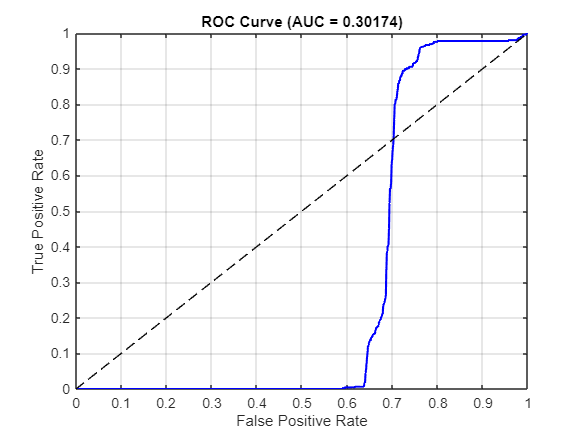

[X, Y, T, AUC] = perfcurve(testTargets, predictedTestOutputs, 1);
figure;
plot(X, Y, '-b', 'LineWidth', 1.5);
hold on;
plot([0 1], [0 1], '--k');  % Diagonal line for random guessing
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curve (AUC = ', num2str(AUC), ')']);
grid on;

% Save the ROC curve as a high-resolution PNG file
exportgraphics(gcf, '../outputs/multiclass_roc_curve_best_feasible.png', 'Resolution', 300);

fprintf('ROC curve saved as "../outputs/multiclass_roc_curve_best_feasible.png" with high resolution.\n');

ROC curve saved as "../outputs/multiclass_roc_curve_best_feasible.png" with high resolution.


%Observation: low AUC value, model performance is poor